# **Workshop** - Gyroscope Model Parameters

*This script defines all the parameters needed to run the workshop_gyroscope.slx model.*

The system that we'll consider is shown below:

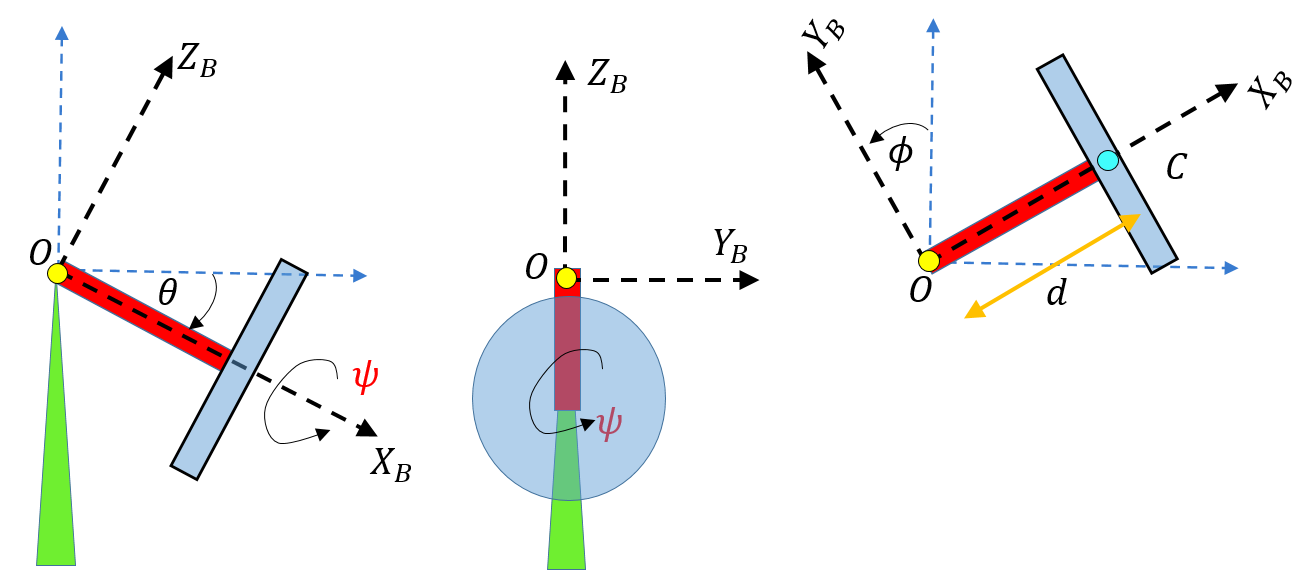

## Our system geometry:

Let's define some of the geometry and mass parameters of our system.

r = 20/100;    % (m),  wheel radius
t =  2/100;    % (m),  wheel thickness
m =  4;        % (kg), wheel mass
d =  7/100;    % (m),  distance from pivot point O to the 
               %      center of mass of the wheel !
rr = 0.01;     % (m),  rod diameter
tr =  d- t/2;  % (kg), rod length  
mr = 0.1;        % (kg), rod mass
     

## The inertia matrix for solid cylinder:

Let's calculate the inertia matrix of the wheel.  First we'll determine the inertia about a frame attached to the center of mass *C* of the wheel, then we'll apply the Parallel axis theorem to calculate the inertia about the pivot point *O*. (consult the following reference for inertias of cylinders  [https://en.wikipedia.org/wiki/List_of_moments_of_inertia](https://en.wikipedia.org/wiki/List_of_moments_of_inertia)).

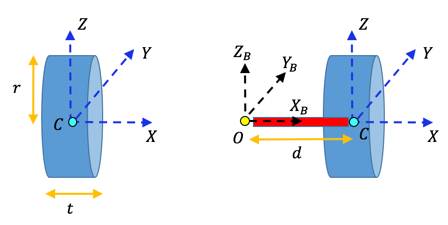

Here's the moment of inertia matrix $^B_CI$ about the cylinder's center of mass:

Ic = [ (m*r^2)/2,   0,                     0;
       0,           m*(3*r^2 + t^2)/12,    0;
       0,           0,                     m*(3*r^2 + t^2)/12;
     ];

% extract the spin axis Inertia term
Ic_xx_val = Ic(1,1);

And here's the cylinder's moment of inertia matrix $^B_OI$ about the pivot point "O" - note we're simply using the Parallel axis theorem:

dx = d;   dy = 0;   dz = 0;

Io = Ic  +  m*[  (dy^2 + dz^2),        (-dx*dy),        (-dx*dz);
                      (-dy*dx),   (dx^2 + dz^2),        (-dy*dz);
                      (-dz*dx),        (-dz*dy),   (dx^2 + dy^2);  ];                  

Note how the Inertia matrix is still (as expected) a diagonal matrix

% echo the Inertia matrix
Io;


## Start a new Simscape™ Multibody™ model 

Let's open a blank Simscape Multibody model template with commonly used blocks 

smnew